Eksamens nr 185432                                                    M4TRM1-03                                         Termodynamik  10-06-2023

# Eksamen E2022

## Introduktion og formalia

Opgaven er lavet i Matlab med coolprop til at trække tabelværdier ud.

Således kan opgaverne laves i den rækkefølge som de udregnes.

clear all
clf
% Importer CoolProp-modul
CoolProp = py.importlib.import_module('CoolProp.CoolProp');
% Stof 
fluid = 'R717';

## Opgave 1

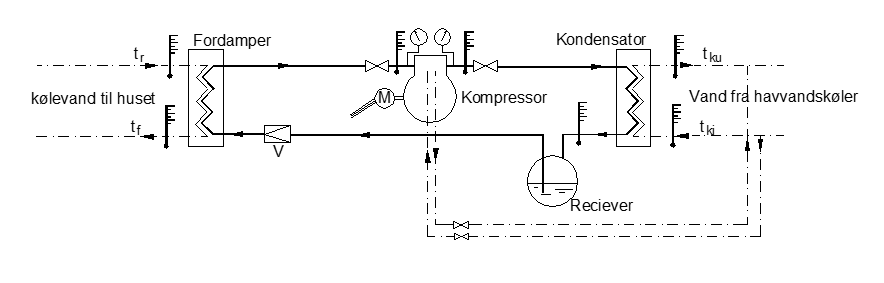

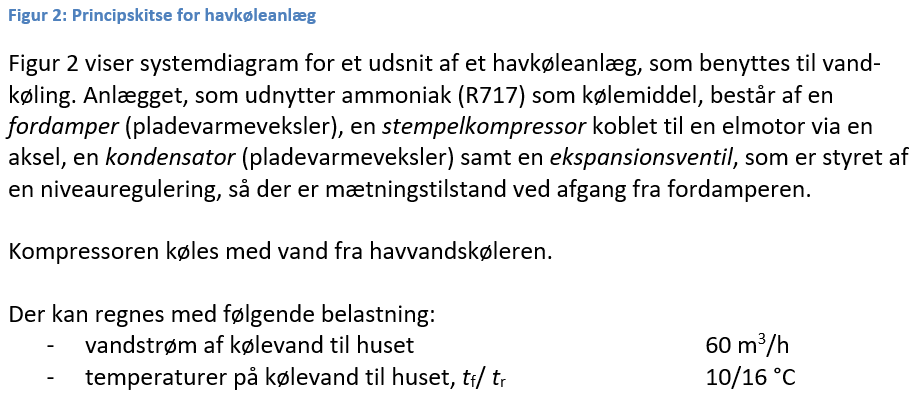

Driftsforhold for køleanlægget:

- fordampningstemperatur                                                         7,5*°C*

- kondenseringstemperatur                                                       33,0 °C

- underkøling i kondensatoren                                                   5 K

- trykrørstemperatur ved udstrømning fra kompressor           85 °C

- Tilført el-effekt til kompressoren                                            75 kW

### a) Optegn køleprocessen i log *p,h*-diagram for R 717

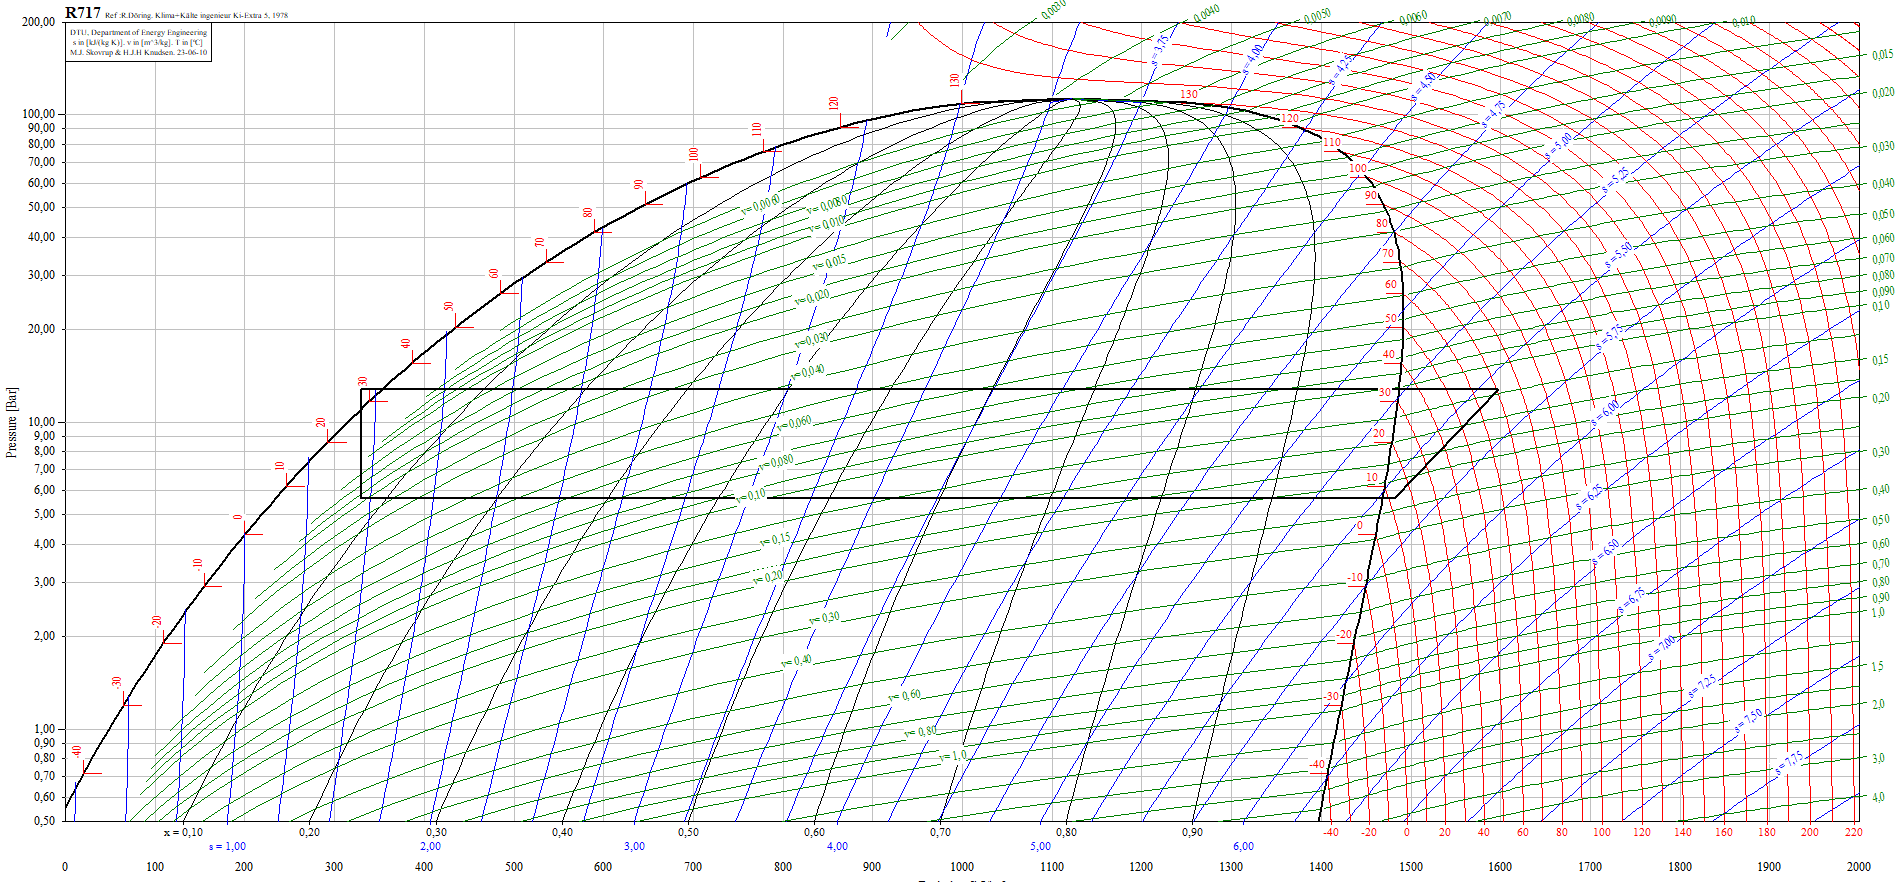

### b) den nødvendige massestrøm af kølemiddel

Vi opskriver værdierne gevet i opgaven

enthalpi fra collpack

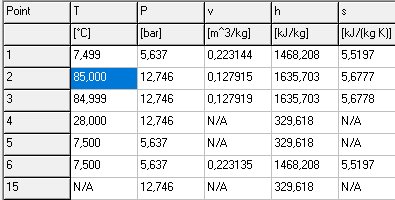

h_1 = 1468.208 * 1e3;
h_2 = 1635.703 * 1e3;%1580.748 * 1e3;
% h_2s = 
h_3 = 329.618 * 1e3;
h_4 = h_3;

Energiligningen for fordamperen opstilles


$$\Phi _{0} + q_{\mathrm{mR}}\,\left(h_{1}-h_{4}\right)=0$$


Vi finder $\Phi_0$ ved at finde den mængde energi vandet overføre pr sekund det løber forbi.

q_vW = 60 / 3600 % m^3/s

q_vW = 0.0167

t_f = 10 + 273.15; %C
t_r = 16 + 273.15; %C
Delta_tW = t_r - t_f

Delta_tW = 6

c_pW = CoolProp.PropsSI('O', 'P', 101325, 'T', (t_r + t_f)/2, 'Water') % den specifikke varmekapacitet af vand

c_pW = 4.1811e+03

rho_W = CoolProp.PropsSI('D', 'P', 101325, 'T', (t_r + t_f)/2, 'Water')

rho_W = 999.3801

Phi_0 = q_vW * rho_W * c_pW * Delta_tW

Phi_0 = 4.1785e+05

syms q_mR
eq_energi_4 = q_mR * (h_4 - h_1) + Phi_0 == 0;

q_mR = vpasolve(eq_energi_4, q_mR)

$$q\_mR = 0.36698833580807394496978424929692$$

Vi får således masse strømmen af fluidet til $q_{mR} = 0.37 \text{kg/s}$

### c) varmefluxen, som skal bortledes fra kompressoren

Vi opstiller energiligningen for kompressoren


$$P_{el} + \Phi _{\mathrm{komp}} - q_{\mathrm{mR}}\,\left(h_{1}-h_{2}\right)=0$$


syms Phi_komp
P_el = 75000; % W
eta_motor = 0.9

eta_motor = 0.9000

P_a = P_el * eta_motor

P_a = 67500

eq_energi_1 =  q_mR * (h_1 - h_2) + P_a  == Phi_komp;
Phi_komp = vpasolve(eq_energi_1, Phi_komp)

$$Phi\_komp = 6031.288693826654587285987164012$$

Der

### d) kompressorens isentrope virkningsgrad, idet elmotorens virkningsgrad er 90 %

  = $h_{2s}$

syms h_2s
% eq_energi_1 =  q_mR * (h_1 - h_2s) + P_a  == 0;
h_2s = 1580.748 * 1e3;
syms P_is
eq_energi_1s =  q_mR * (h_1 - h_2s) + P_is == 0;

P_is = vpasolve(eq_energi_1s, P_is)

$$P\_is = 41300.867311840641766899519415876$$

% eta_sK = (h_2s - h_1)/(h_2 - h_1) % for ukølet process

eta_sK = P_is/P_a

$$eta\_sK = 0.61186470091615765580591880616112$$

Vi får nu en virkningsgrad på $\eta_{sK} = 0,61$

### e) anlæggets effektfaktor

Phi_0/P_el

ans = 5.5713

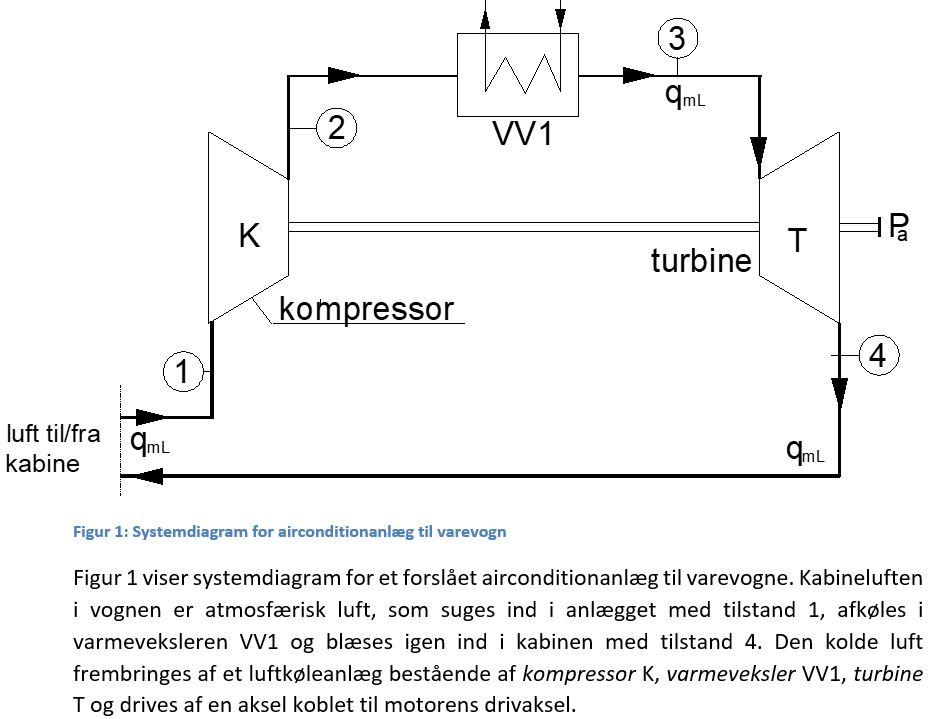

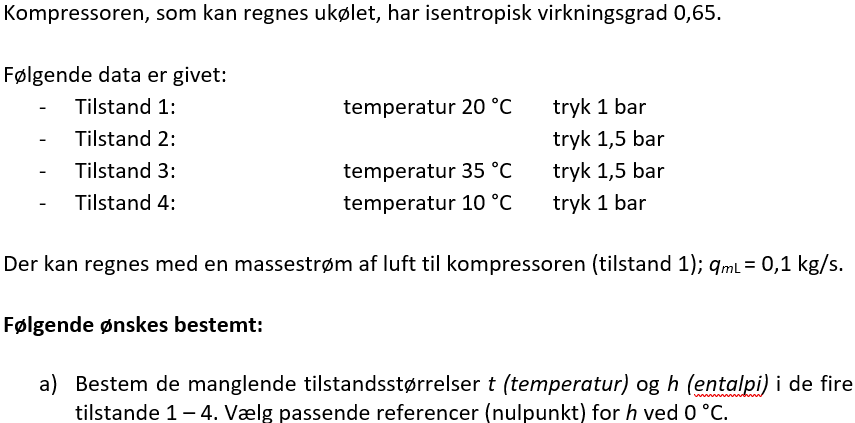

**Område 1**

clear all
clf
format shortg
% Importer CoolProp-modul
CoolProp = py.importlib.import_module('CoolProp.CoolProp');
% Stof 
fluid = 'Air';



eta_sK = 0.65;
T_1 = 20 + 273.15;
P_1 = 1e5; %ps
h_1 = CoolProp.PropsSI('H', 'P', P_1, 'T', T_1, fluid);
rho_1 = CoolProp.PropsSI('D', 'P', P_1, 'T', T_1, fluid);
v_1 = 1/rho_1;
x_1 = CoolProp.PropsSI('Q', 'P', P_1, 'T', T_1, fluid);
s_1 = CoolProp.PropsSI('S', 'P', P_1, 'T', T_1, fluid);

**Område 2**

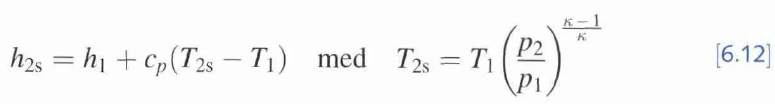

P_2 = 1e5 * 1.5; %ps

c_p1 = CoolProp.PropsSI('Cpmass', 'P', P_1, 'T', T_1, fluid)

c_p1 =        1006.1


c_V1 = CoolProp.PropsSI('Cvmass', 'P', P_1, 'T', T_1, fluid)

c_V1 =        717.66


kappa = c_p1 / c_V1

kappa =        1.4019


T_2s = T_1 * (P_2/P_1)^((kappa-1)/kappa)

T_2s =        329.29


h_2s = h_1 + c_p1*(T_2s - T_1)

h_2s =    4.5577e+05


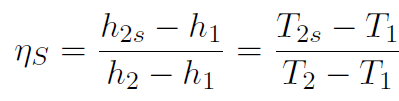

syms h_2
eq_H_2 = eta_sK == ( (h_2s - h_1) / (h_2 - h_1))

$$eq\_H\_2 = \frac{13}{20}=\frac{78081139518241}{2147483648\,\left(h_{2}-\frac{7205375785168903}{17179869184}\right)}$$

h_2 = vpasolve(eq_H_2, h_2)

$$h\_2 = 475345.55344571170952314367661109$$

T_2 = CoolProp.PropsSI('T', 'P', P_2, 'H', double(h_2), fluid);
rho_2 = CoolProp.PropsSI('D', 'P', P_2, 'T', T_2, fluid);
v_2 = 1/rho_2;
x_2 = CoolProp.PropsSI('Q', 'P', P_2, 'T', T_2, fluid);
s_2 = CoolProp.PropsSI('S', 'P', P_2, 'T', T_2, fluid);

**Område 3**

T_3 = 35 + 273.15;
P_3 = P_2;
h_3 = CoolProp.PropsSI('H', 'P', P_3, 'T', T_3, fluid);
rho_3 = CoolProp.PropsSI('D', 'P', P_3, 'T', T_3, fluid);
v_3 = 1/rho_3;
x_3 = CoolProp.PropsSI('Q', 'P', P_3, 'T', T_3, fluid);
s_3 = CoolProp.PropsSI('S', 'P', P_3, 'T', T_3, fluid);

**Område 4**

T_4 = 10 + 273.15;
P_4 = P_1;
h_4 = CoolProp.PropsSI('H', 'P', P_4, 'T', T_4, fluid); %h_3; 
rho_4 = CoolProp.PropsSI('D', 'P', P_4, 'T', T_4, fluid);
v_4 = 1/rho_4;
x_4 = CoolProp.PropsSI('Q', 'P', P_4, 'T', T_4, fluid);
s_4 = CoolProp.PropsSI('S', 'P', P_4, 'T', T_4, fluid);

**Table**

Temperatur_C = double([T_1, T_2, T_3, T_4]') - 273.15;
Tryk = double([P_1, P_2, P_3, P_4]') / 1e5;
Entalpi  = double([h_1, h_2, h_3, h_4]'/1e3);
% Densitet = double([rho_1, rho_2, rho_3, rho_4]');
Specifik_vol = double([v_1, v_2, v_3, v_4]');
Kvalitet = double([x_1, x_2, x_3, x_4]');
Entropy = double([s_1, s_2, s_3, s_4]');
T = table(Temperatur_C, Tryk, Entalpi, Entropy, Specifik_vol, Kvalitet, ... %, Densitet
    VariableNames={'Temperatur (C)', 'Tryk (bar)', 'Spec entropy s (kJ/kg)', 'Spec entalpi h (kJ/kg)', 'Spec volumen (m^3/kg)', 'Kvalitet x'})

T = 4×6 table
    Temperatur (C)    Tryk (bar)    Spec entropy s (kJ/kg)    Spec entalpi h (kJ/kg)    Spec volumen (m^3/kg)    Kvalitet x
    ______________    __________    ______________________    ______________________    _____________________    __________

            20             1                419.41                    3867.3                   0.84117               -1    
        75.607           1.5                475.35                    3925.6                   0.66741               -1    
            35           1.5                 434.4                    3800.8                   0.58948               -1    
            10             1                409.35                    3832.3                   0.81239               -1    


### b) Energibalancen på kabinen og anlæggets kuldeydelse


$$q_{mL} (h_4 - h_1) = \Phi_{kabine}$$


q_mL = 0.1;
syms Phi_0
eq_energi_4 = q_mL * h_4 + Phi_0 == q_mL * h_1;
Phi_0 = vpasolve(eq_energi_4,Phi_0)

$$Phi\_0 = 1005.9799557351507246494293212891$$

% Phi_kabine = q_mL * (h_1 - h_4)

anlægget kuldeydelse er således $\Phi_{kabine} = \Phi_0 = 1006 \text{ W}$

% eq_energi_1 = q_mL * (h_1 - h_2) - Phi_komp + P_a == 0
% eq_energi_2 = q_mR * (h_2 - h_3) - Phi_K == 0
% eq_energi_3 = h_3 == h_4
% eq_energi_4 = q_mR * (h_4 - h_1) + Phi_0 == 0

### c) Energibalancen på kompressoren og dens tilførte effekt fra turbinen

P_K = q_mL * (h_2 - h_1) %regnes ukølet

$$P\_K = 5593.7482988491224554868844839243$$

Således er aksel effekten $\Phi_a = 5594\text{ W}$

P_a = P_K + q_mL * h_4 - q_mL * h_3

$$P\_a = 3088.889667533888803938260445228$$

Således bliver aksel effekten $P_a = 3089 \text{W}$ 

syms Phi_VV
eq_energi_2 = q_mL * h_2  - Phi_VV == q_mL * h_3;
Phi_VV = vpasolve(eq_energi_2, Phi_VV)

$$Phi\_VV = 4094.8696232690351630131212564615$$

Varme veksleren har således en energi på $\Phi_{VV} = 4095 \text{W}$

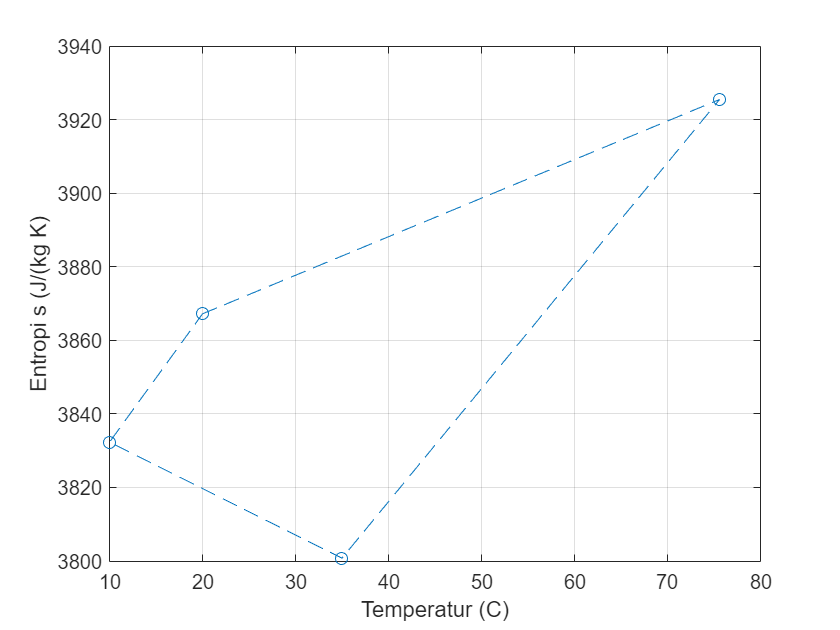

Entropy(end+1) = Entropy(1);
Temperatur_C(end+1) = Temperatur_C(1);
plot(Temperatur_C, Entropy, 'o--')
xlabel('Temperatur (C)')
ylabel('Entropi s (J/(kg K)')
grid('on')